# Übung 2

## 2.1 Vorbereitung

Stellen Sie durch zwei geeignete Matlab-Befehle sicher, dass

- der Workspace initialisiert ist,

- alle Figures (Diagrammfenster) geschlossen sind und

- die Darstellung der Ergebnisse 'compact', also ohne zusätzliche Leerzeilen erfolgt.

close all
clear all
format compact

Im Folgenden ergänzen/erweitern Sie dieses Script. Sofern nicht anders angegeben, unterdrücken Sie die Ergebnisausgabe (Strichpunkt am Zeilenende). Wenn Sie alle Übungsaufgaben bearbeitet haben, publizieren ('publishen') Sie das Skript als PDF.

## 2.2 Signalgenerierung

Erzeugen Sie einen Vektor *s* mit


$$ s = \sum_{m=1}^M 1/m*sin(m*2*pi*n/N) $$


mit *N*= 2^6, *n*= 0:(N-1), M= 10, m= alle ungerade <= M

M = 10;

N = 2^6;
%N = 5;

% create a vector that stores the values from 0 to M
s = [0 : 1 : N-1];

% arrayfun(func(), B) - apply a function func() to each 
% element of the array B and return the result.
%
% @(x) is a iterator over the array B and contains the 
% current value
s_10 = arrayfun(@(x) calc_sum(M, N, x), s)

s_10 =          0    0.4656    0.7957    0.9254    0.8876    0.7822    0.7103    0.7173    0.7789    0.8353    0.8414    0.7991    0.7491    0.7344    0.7652    0.8126    0.8349    0.8126    0.7652    0.7344    0.7491    0.7991    0.8414    0.8353    0.7789    0.7173    0.7103    0.7822    0.8876    0.9254    0.7957    0.4656    0.0000   -0.4656   -0.7957   -0.9254   -0.8876   -0.7822   -0.7103   -0.7173   -0.7789   -0.8353   -0.8414   -0.7991   -0.7491   -0.7344   -0.7652   -0.8126   -0.8349   -0.8126


## 2.3 Plotten der Daten

Plotten Sie die Daten des Vektors *s* in ein Diagramm *s*(*n*). Zeigen Sie zunächst nur die berechneten Punkte in blau an (ohne Verbindungslinie).

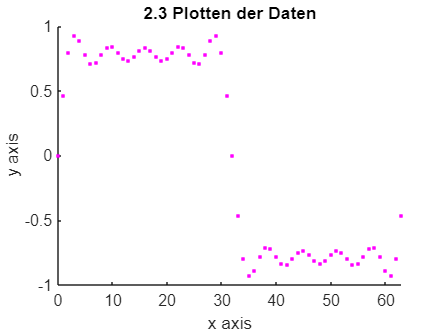

figure()
newplot()

title('2.3 Plotten der Daten')
xlabel('x axis')
ylabel('y axis')

hold on

plot(s, s_10, 'linestyle', 'none', 'marker', '.', "Color", "magenta")

hold off

## 2.4 Neue Funktion (*genRect*)

Erzeugen Sie eine Matlab-Funktion *s* = *genRect*(*N*, *M*), welche das Signal aus Aufgabe 1.2 für gegebene *N* und *M* berechnet und als Vektor *s* zurückgibt.

Erzeugen Sie die neue Funktion über das Matlab Menü (New, Function), ersetzen Sie die von Matlab erzeugten Kommentare durch eigene, sinnvolle Texte und speichern Sie die fertige Funktion genRect im selben Verzeichnis wie dieses Script.

Dateiinhalt genRect.m hier einfügen mit "type genRect.m" type genRect.m

Verwenden Sie dann die Funktion *genRect*(*N*, *M*) zur Erzeugung des Signale *s1* mit *M*= 1,  *s2* mit *M*= 5, *s3* mit *M*= 10 und *s4* mit *M*= 50.

M = 1;
s_1 = arrayfun(@(x) calc_sum(M, N, x), s)

s_1 =          0    0.0980    0.1951    0.2903    0.3827    0.4714    0.5556    0.6344    0.7071    0.7730    0.8315    0.8819    0.9239    0.9569    0.9808    0.9952    1.0000    0.9952    0.9808    0.9569    0.9239    0.8819    0.8315    0.7730    0.7071    0.6344    0.5556    0.4714    0.3827    0.2903    0.1951    0.0980    0.0000   -0.0980   -0.1951   -0.2903   -0.3827   -0.4714   -0.5556   -0.6344   -0.7071   -0.7730   -0.8315   -0.8819   -0.9239   -0.9569   -0.9808   -0.9952   -1.0000   -0.9952



M = 5;
s_5 = arrayfun(@(x) calc_sum(M, N, x), s)

s_5 =          0    0.2891    0.5466    0.7470    0.8754    0.9300    0.9215    0.8703    0.8014    0.7388    0.7003    0.6946    0.7198    0.7651    0.8147    0.8526    0.8667    0.8526    0.8147    0.7651    0.7198    0.6946    0.7003    0.7388    0.8014    0.8703    0.9215    0.9300    0.8754    0.7470    0.5466    0.2891    0.0000   -0.2891   -0.5466   -0.7470   -0.8754   -0.9300   -0.9215   -0.8703   -0.8014   -0.7388   -0.7003   -0.6946   -0.7198   -0.7651   -0.8147   -0.8526   -0.8667   -0.8526



M = 10;
s_10 = arrayfun(@(x) calc_sum(M, N, x), s)

s_10 =          0    0.4656    0.7957    0.9254    0.8876    0.7822    0.7103    0.7173    0.7789    0.8353    0.8414    0.7991    0.7491    0.7344    0.7652    0.8126    0.8349    0.8126    0.7652    0.7344    0.7491    0.7991    0.8414    0.8353    0.7789    0.7173    0.7103    0.7822    0.8876    0.9254    0.7957    0.4656    0.0000   -0.4656   -0.7957   -0.9254   -0.8876   -0.7822   -0.7103   -0.7173   -0.7789   -0.8353   -0.8414   -0.7991   -0.7491   -0.7344   -0.7652   -0.8126   -0.8349   -0.8126



M = 50;
s_50 = arrayfun(@(x) calc_sum(M, N, x), s)

s_50 =          0    0.7838    0.8337    0.8025    0.7661    0.7683    0.7928    0.8008    0.7851    0.7727    0.7809    0.7949    0.7930    0.7795    0.7760    0.7874    0.7954    0.7874    0.7760    0.7795    0.7930    0.7949    0.7809    0.7727    0.7851    0.8008    0.7928    0.7683    0.7661    0.8025    0.8337    0.7838    0.0000   -0.7838   -0.8337   -0.8025   -0.7661   -0.7683   -0.7928   -0.8008   -0.7851   -0.7727   -0.7809   -0.7949   -0.7930   -0.7795   -0.7760   -0.7874   -0.7954   -0.7874


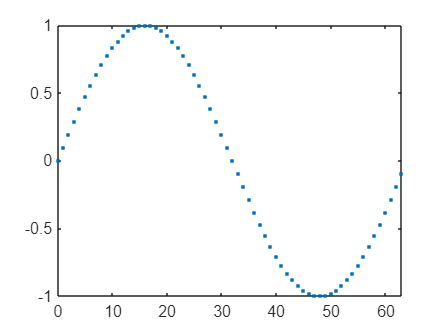


figure
newplot()
title('2.4 Neue Funktion (genRect)')

plot(s, s_1, 'linestyle', 'none', 'marker', '.')

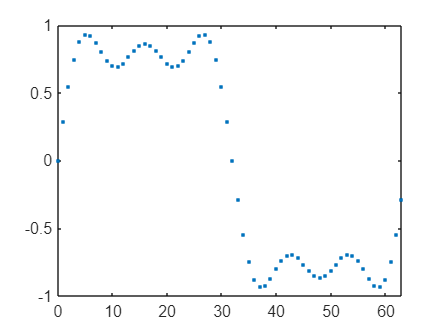

plot(s, s_5, 'linestyle', 'none', 'marker', '.')

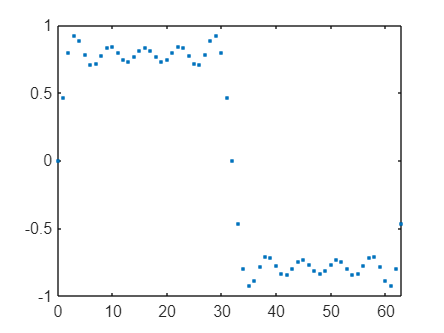

plot(s, s_10, 'linestyle', 'none', 'marker', '.')

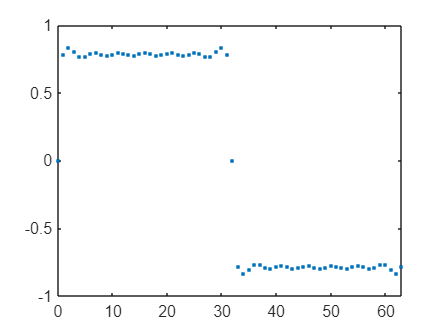

plot(s, s_50, 'linestyle', 'none', 'marker', '.')

Plotten Sie nun *s1* bis *s4* in ein weiteres Diagramm, geben Sie dem Diagramm eine Überschrift, beschriften Sie die Achsen und erzeugen Sie eine Legende. Diesmal geben Sie keine Farben vor und verbinden die Datenpunkte.

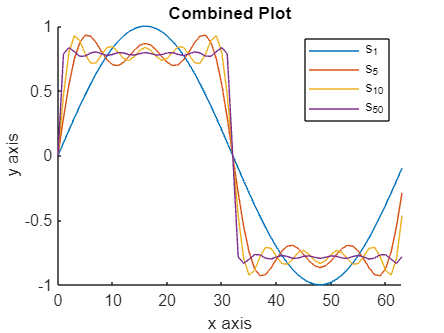

figure
newplot()

title('Combined Plot')
xlabel('x axis')
ylabel('y axis')

hold on

plot(s, s_1)
plot(s, s_5)
plot(s, s_10)
plot(s, s_50)

legend('s_1', 's_5', 's_10', 's_50')

hold off

## 2.5 Subplots

Erzeugen Sie in einem neuen Diagramm einen 2x2 Subplot und stellen sie die Signale *s1* bis *s4* jeweils in einem eigenen Diagramm innerhalb des Subplots dar.

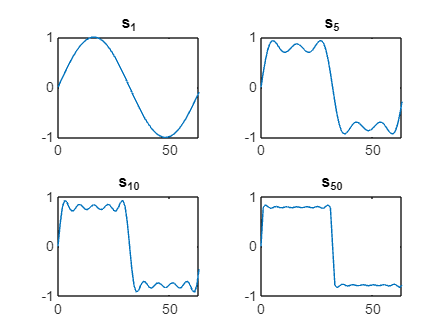

figure
newplot()

title('Tiled Plot')
xlabel('x axis')
ylabel('y axis')
tiledlayout(2, 2)

%hold on

tile_1 = nexttile;
plot(tile_1, s, s_1)
title('s_1')

tile_2 = nexttile;
plot(tile_2, s, s_5)
title('s_5')

tile_3 = nexttile;
plot(tile_3, s, s_10)
title('s_10')

tile_4 = nexttile;
plot(tile_4, s, s_50)
title('s_50')

%legend('s_1', 's_5', 's_10', 's_50')

hold off

## 2.6 Neue Funktion (*myPlot*)

Um jetzt nicht jeden der Plots explizit mit Überschrift und Achsenbeschriftung ausstatten zu müssen, erzeugen Sie eine Matlab-Funktion *myPlot*, die den plot generiert und beschriftet. Die Texte sollen als Parameter übergeben werden, eine Ergebnisrückgabe erfolgt nicht. Überschreiben Sie einfach die Plots des aktuellen Subplots.

%figure
%newplot()

%%tiledlayout(1, 1)

%title('2.6 Neue Funktion (myPlot)')
%xlabel('X Achse')
%ylabel('Y Achse')

%hold on

%%plot(s, s_50)
%myPlot('plot', s, s_50, '2.6 Neue Funktion (myPlot)', 'xLabel', 'yLabel')

%hold off

Dateiinhalt myplot.m hier einfügen mit "type myPlot.m" type myPlot.m

## 2.7 Alternative Plot-Formate: Stairs, Stem und Bar

Stellen Sie das Signal *s1*, jeweils mit voller Beschriftung als Stair-, Stem- und Bar-Diagramm dar. Statten Sie hierzu Ihre Funktion *myPlot* mit einem weiteren Parameter aus, mit dem sich die Darstellungsart auswählen lässt. ACHTUNG: Wenn Sie die Definition von *myPlot* ändern, müssen Sie auch die Lösung der vorhergehenden Aufgabe anpassen, damit Ihr Script ablauffähig bleibt!

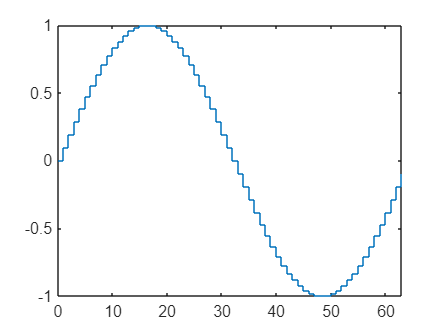

figure();
myPlot( 'stairs', s, s_1, 'Treppendiagramm', 'n /1', 's_1 /1' );

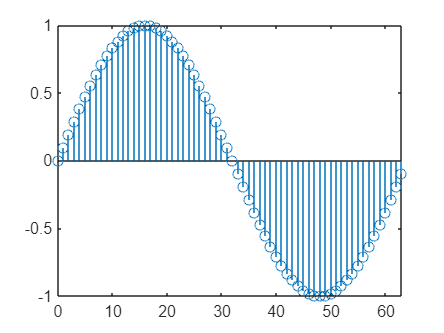


figure();
myPlot( 'stem',   s, s_1, 'Liniendiagramm',  'n /1', 's_1 /1' );

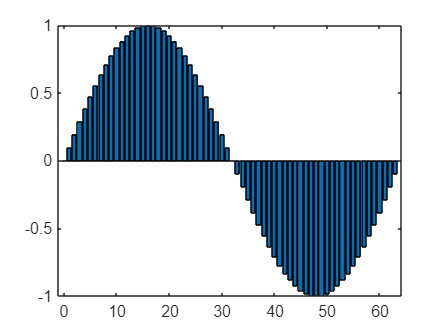


figure();
myPlot( 'bar',    s, s_1, 'Balkendiagramm',  'n /1', 's_1 /1' );

function result = calc_sum(M, N, n)
    %display(n)
    result = 0;
    for m = 1 : M
        if mod(m, 2) == 1
            temp = 1/m * sin(m * 2 * pi * n/N);
            result = result + temp;
        end
    end
end

function myPlot(graphic, x_data, y_data, tTitle, xLabel, yLabel)

    %newplot()
    
    title(tTitle)
    xlabel(xLabel)
    ylabel(yLabel)
    
    %hold on
    
    if strcmp(graphic, 'plot')
        plot(x_data, y_data)
    end

    if strcmp(graphic, 'stem')
        stem(x_data, y_data);
    end

    if strcmp(graphic, 'stairs')
        stairs(x_data, y_data)
    end

    if strcmp(graphic, 'bar')
        bar(x_data, y_data)
    end
    
    %legend('s_1', 's_5', 's_10', 's_50')
    
    %hold off
end